# SVM classifier on paired data using CANlab tools

Support Vector Machines are a fast and efficient way to identify multivariate patterns that separate two conditions. For example, we might want to identify brain patterns that predict (or 'decode'):

- whether a working memory task was difficult or easy

- whether a person will remember or forget an image

- whether a person is experiencing high or low pain

- whether a person is actively reappraising (regulating) emotion or not

SVMs are called "maximum margin classifiers" because they identify a hyperplane (think of a 2-D boundary like a curtain, but in multidimensional space) that maximizes the separation (or  "margin", in the sense that there is a buffer of empty space) between images belonging to the two classes. The outcome (or response) data is often labeled with values of 1 and -1, i.e., "on"/"off" labels for the classes.

SVMs can be run on any set of images using whole-brain patterns, multiple regions of interest, or other derived ***features ***(input variables). The SVM will try to define a hyperplane (boundary) that separates the classes of all the images (or other measures) fed into it. It delivers two outputs: 

- A **weight map**, which is a value for each feature (brain voxel in an image). The weights specify a linear combination that is orthogonal to the hyperplane, so that a higher combination indicates the "on" class and a lower combination indicates the "off" class. If brain images are fed in as input features, the weight map will be a voxel-wise brain map. 

- **Scores** for each image.  The scores are the dot product of the weight map and the input data for each observation (i.e., the linear combination discussed above), plus an intercept, or "offset" value. The offset is estimated so that in the training data, scores > 0 are predicted to be "on" and scores < 0 are predicted to be "off". 

The weight map plus the intercept is the "model". 

The scores can be evaluated for accuracy using **cross-validation** or by applying the model to an **independent test dataset**. Applying the model to a dataset with independent errors is the only way to prevent *overfitting* and provide a valid estimate of the model's classification performance.

The comparisons between classes can either be **between-person**, where different examples of "on" and "off" images come from different participants, or **within-person** (or paired), where there is one or more example of an "on" and and "off" condition for each participant.  The SVM classifier will simply try to separate the classes based on the features fed into it, regardless of the identity of the participant. But when it delivers scores back, we can keep track of which scores came from the same person, and compute a within-person,** forced-choice** accuracy. This asesses whether, given two images from the same participant, I can guess which one was collected during the "on" and which during the "off" condition. This is usually quite a bit higher than the **single-interval** accuracy, which just makes a guess for each image based on the absolute SVM score.  There are many individual differences that can influence the overall score (e.g., vasculature, overall BOLD magnitude, variations in brain morphology and normalization) and lead to poor single-interval accuracy, but many of these sources drop out if we are able to compare paired images from the same person.

In this lab, we'll use the function `canlab_run_paired_SVM` to train on a mix of images, but calculate the  forced-choice accuracy within a person. 

### Set up directory and load files


dat = load_image_set('Kragel18_alldata');

Loading /Users/torwager/Dropbox (Dartmouth College)/COURSES/Courses_Dartmouth/2021_3_Spring_fMRI_Class/PSYC60_Shared_resources_for_students/datasets/kragel_2018_nat_neurosci_270_subjects_test_images.mat
Loaded images:
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain1
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
ThermalPain2
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain1
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2
VisceralPain2


This loads the data we'll use. The dataset is from [Kragel et al. 2018, Nature Neuroscience](https://www.nature.com/articles/s41593-017-0051-7). It consists of 270 participants systematically sampled from 18 studies of 3 domains:

- **pain** of three subtypes: thermal, visceral, and mechanical

- **cognitive control** of three subtypes: working memory, response competition, and response selection

- **negative affect** of three subtypes: aversive images from the IAPS set, social affect (romantic rejection and vicarious pain), and aversive sounds from the IADS set.

Each subdomain includes  two studies per type, with n = 15 per study. The *.metadata_table *attribute contains a Matlab table object with the domain, subdomain, and study indicator.

dat.metadata_table(1:5, :)

### Look at the data and consider scaling options

It's always a good idea to look at your data!  With this dataset, because images come from different studies, there is no guarantee they are on the same scale.  We'll do a simple transformation here, z-scoring each participant's data image. This subtracts the mean and divides by the standard deviation (across voxels) of each image. After z-scoring, effectively, we're analyzing the pattern of values across voxels rather than their absolute intensity.

Z-scoring treats the images independently and does not depend on estimating any parameters (e.g., means, ranks) across the group, which is crucial for maintaining validity when using cross-validation. 

%% z-score each participant

dat = rescale(dat, 'zscoreimages');


#### Questions to answer

- How important is scaling here? What was wrong with the data, if anything, before scaling?

- What kind of information that could be useful for classification might you be losing by scaling each image?

### Define training/cross-validation and test (generalization) datasets 

We'll use some Matlab code for manipulating sets to pull out a training set for the classification Pain vs. Cognitive Control.  We'll train on 3 studies of each, across 3 subdomains each. 

#### Training dataset

wh_studies = [1 3 5 7 9 11];
wh_subjects = ismember(dat.metadata_table.Studynumber, wh_studies);

% List the unique subdomains
unique(dat.metadata_table.Subdomain(wh_subjects))

ans = 6×1 cell array
    {'Inhibition'    }
    {'Mechanical'    }
    {'ResponseSelect'}
    {'Thermal'       }
    {'Visceral'      }
    {'WorkingMem'    }


Now we'll define a training_dat object, selecting only the included subjects. We do this by calling remove_empty() to exclude those that are not  (~) in the list.

training_dat = dat;
training_dat = remove_empty(training_dat, [], ~wh_subjects);

% We may have to update some fields manually, like the metadata table
training_dat.metadata_table = training_dat.metadata_table(wh_subjects, :);

To train the SVM, we have different options. We can: 

- Use the *predict( )* method after assigning 1 and -1 labels to training_dat.Y

- Use `xval_SVM` on the data matrix, training_dat.dat'

- Separate them into two matched objects, if the images are paired (they're not here).

We'll use the first of these.

wh_studies = [1 3 5];
train_plus = ismember(dat.metadata_table.Studynumber, wh_studies);

wh_studies = [7 9 11];
train_minus = ismember(dat.metadata_table.Studynumber, wh_studies);

% generate vector of outcome labels, 1 and -1. 
% Cast as double because we need numeric (not logical) inputs.
train_Y = double(train_plus) - double(train_minus);

training_dat.Y = train_Y(wh_subjects);

#### Test dataset

We'll use the same type of code to define a test dataset, with different studies from the same subdomain:

wh_studies = [2 4 6];
test_plus = ismember(dat.metadata_table.Studynumber, wh_studies);

wh_studies = [8 10 12];
test_minus = ismember(dat.metadata_table.Studynumber, wh_studies);

% generate vector of outcome labels, 1 and -1. 
% Cast as double because we need numeric (not logical) inputs.
test_Y = double(test_plus) - double(test_minus);

wh_subjects = test_Y ~= 0;  % logical vector for any subject in test set

test_dat = dat;
test_dat = remove_empty(test_dat, [], ~wh_subjects);

test_dat.Y = test_Y(wh_subjects);


#### Questions to answer

- Why is it important to separate training and test datasets?

- Have we done this adequately here? Why or why not?

- What are the advantages, if any, of including different kinds of studies with different subdomains in our training set?

- What are the disadvantages of the above, if any?

- What alternative splits of training and test data could make sense here, and why would they be advantageous?

### Train the SVM to discriminate Pain vs. Cognitive Control

Our first goal is to train a classifier that separates pain from cog control:

[cverr, stats, optout] = predict(training_dat, 'cv_svm');

Cross-validated prediction with algorithm cv_svm,   5 folds
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 1.44 sec

Completed fit for all data in:   0 hours   0 min  2 secs 
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.66 sec
Fold 1/5 done in:   0 hours   0 min  1 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.55 sec
Fold 2/5 done in:   0 hours   0 min  1 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.58 sec
Fold 3/5 done in:   0 hours   0 min  1 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.60 sec
Fold 4/5 done in:   0 hours   0 min  1 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.59 sec
Fold 5/5 done in:   0 hours   0 min  1 sec

Total Elapsed Time =   0 hours   0 min  6 sec
Number of unique values in dataset: 201275  Bit rate: 17.62 bits


*predict() *runs 5-fold cross-validation by default. There are optional inputs for:

- Controlling the cross-validation. You should always leave out ALL images from the same participant together in a cross-validation fold. If you have more than one input image per condition per subject, you will need to customize your holdout set, e.g., with *stratified_holdout_set*( ) or *xval_stratified_holdout_leave_whole_subject_out*( ).

- Running a boostrap test to obtain P-values for the SVM weights and identify voxels that make a significant contribution to prediction

Other related CANlab functions are *xval_SVM( )*, *xval_SVR( ), canlab_run_paired_SVM( ),* and other functions that start with *xval_*

**paired_d** is the cross-validated effect size in paired (forced-choice) comparison. 0.5 is a medium effect, 0.7 a large effect, and anything larger is "very large". 

**stats **contains a stats output structure for the SVM. This includes specific fields:

- stats.paired_hyperplane_dist_scores: The distance from the hyperplane for the paired pos - neg images for each unit (e.g., subject). Positive indicates correct classification.

-  stats.paired_d:  Simple Cohen's d effect size for forced-choice cross-validated classification. This is the main metric of interest for evaluating classification performance.

- stats.paired_accuracy:  Accuracy of forced-choice (two choice) classification, cross-validated

- stats.ROC:  Additional output from *roc_plot( )*, which caculates a Receiver Operating Characteristic curve. This output includes the sensitivity/specificity/PPV (which will all be identical for two-choice paired classification)

- stats.weight_obj: An fmri_data object with the weights. If bootstrapping, a statistic_image object including P-values that can be thresholded.

### Display the cross-validated results

Display the unthresholded weight map:

We can extract statistics from the stats structure in different ways.  

**Confusion matrix. **Let's get a confusion matrix, and a table for each true class. The confusion matrix shows the proportions (or counts) of each true class (rows) assigned to each class (columns). It can thus reveal what kinds of errors the model is making.

[m,aprime,corr,far,missclass, mprop, statstable] = confusion_matrix(stats.Y, stats.yfit);

% Create a table object from the matrix mprop, which shows proportions of
% each true class (rows) assigned to each class (columns)
mytable = array2table(mprop, 'VariableNames', {'Pred Cog' 'Pred Pain'}, 'RowNames', {'Actual Cog' 'Actual Pain'});
disp(mytable)

                   Pred Cog    Pred Pain
                   ________    _________

    Actual Cog      0.88889     0.11111 
    Actual Pain    0.088889     0.91111 




disp(statstable)

    Freq    Perc_cases     Sens       Spec        PPV      Aprime
    ____    __________    _______    _______    _______    ______

     45        0.5        0.88889    0.91111    0.90909    2.5683
     45        0.5        0.91111    0.88889     0.8913    2.5683



**The ROC plot. **Display the performance in a Receiver Operating Characteristic curve. This plots the Specificity against  1 - Sensitivity (the False Alarm rate). It's possible to have 100% sensitivity by always classifying an observation as a "yes" (1), making 100% false alarms. Likewise,  It's possible to have 100% specificity by always classifying an observation as a "no" (-1). The ROC plot displays the tradeoff curve between the two. A concave curve (high Sensitivity with low [1 - Specificity], i.e., high Specificity) shows good classification performance and indicates true predictive signal. A straight line or a convex curve indicates no true predictive signal. *ROC_plot()* will also choose a threshold that maximizes either the overall accuracy or the balanced accuracy (the average accuracy across classes, even if some classes have fewer observations). The latter is recommended. Here is some of the output of *ROC_plot()*, saved in a structure:

- Sensitivity: Chances of predicting a "yes" given true "yes"

- Specificity: Chances of predicting a "no" given true "no"

- Positive predictive value: Chances of true "yes" given predicted "yes"

- Negative predictive value: Chances of true "no" given predicted "no"

- d or d_a: Effect size for classification; higher values indicate stronger predictive signal.

- AUC: Area under the ROC curve. Higher values indicate more true signal, with a max of 1 (100% sensitivity with 100% specificity, perfect classification).

- sensitivity_ci, other _ci     95% confidence intervals for sensitivity and other statistics

- Accuracy: Overall accuracy at the selected threshold.

create_figure('ROC')

ans =   Figure (ROC) with properties:

      Number: 1
        Name: 'ROC'
       Color: [1 1 1]
    Position: [561 529 560 420]
       Units: 'pixels'

  Show all properties


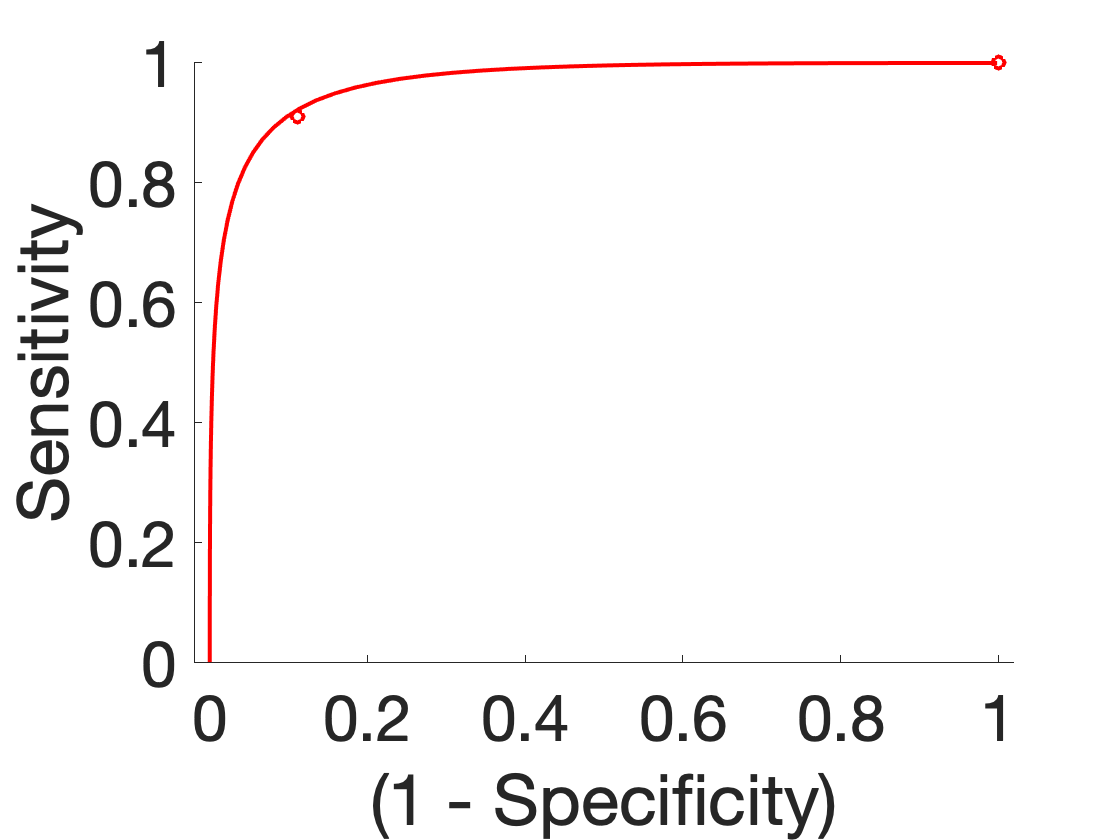


ROC_PLOT Output: Single-interval, Optimal overall accuracy
Threshold:	-1.00	Sens:	 91% CI(82%-98%)	Spec:	 89% CI(79%-98%)	PPV:	 89% CI(79%-98%)	Nonparametric AUC:	0.85	Parametric d_a:	2.64	  Accuracy:	 90% +- 3.2% (SE), P = 0.000000


ROC = roc_plot(stats.yfit, logical(stats.Y > 0), 'color', 'r');

Plot the individual subjects. This is always useful to get a better picture of what the data look like!

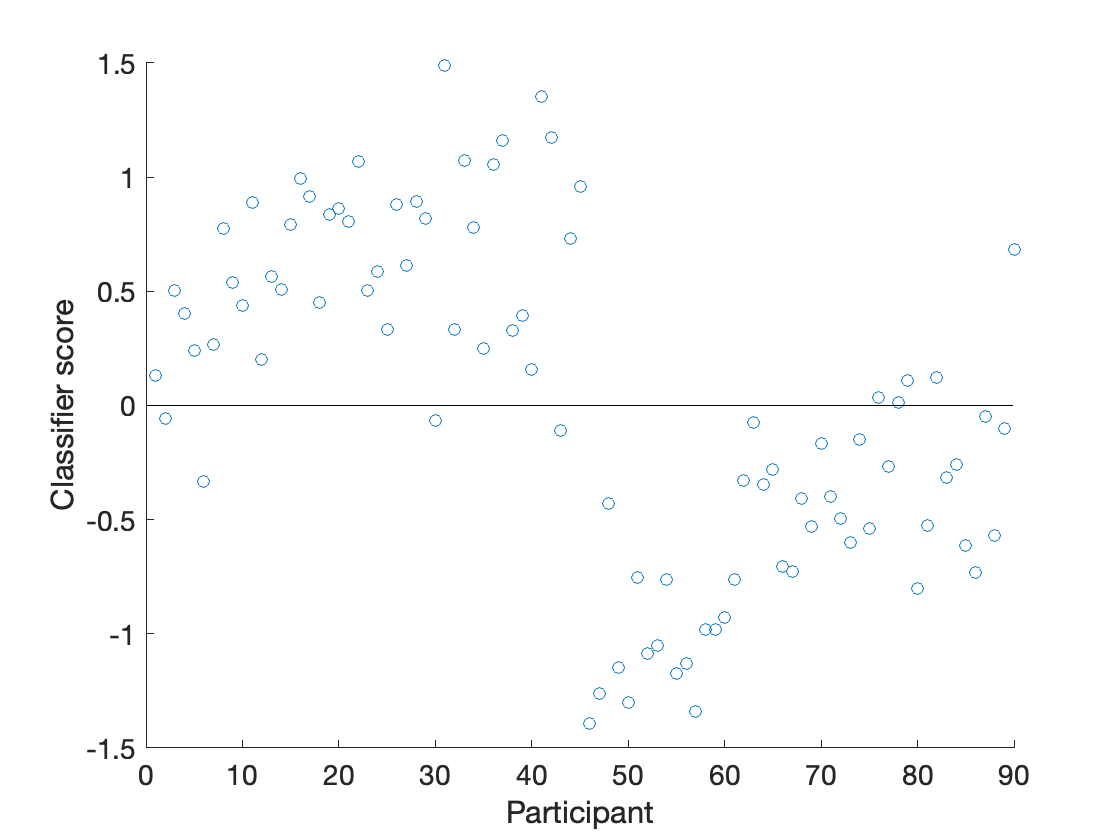

create_figure('subjects');
plot(stats.dist_from_hyperplane_xval, 'o');
plot_horizontal_line(0);
xlabel('Participant'); ylabel('Classifier score');


% Plot the scores
dat_to_plot = {stats.dist_from_hyperplane_xval(stats.Y > 0) stats.dist_from_hyperplane_xval(stats.Y < 0)};

create_figure('SVM distance scores by class');
barplot_columns(dat_to_plot, 'title', 'Training data SVM scores', 'nofigure', 'colors', {[.7 .2 .2] [.5 .3 .7]});

Column   1:	Column   2:	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error       T           P         Cohens_d
    ___________    __________    _________    _______    __________    ________

    {'Col   1'}      0.61095     0.060264      10.138    4.3724e-13     1.5113 
    {'Col   2'}     -0.56656     0.068587     -8.2604    1.7104e-10    -1.2314 



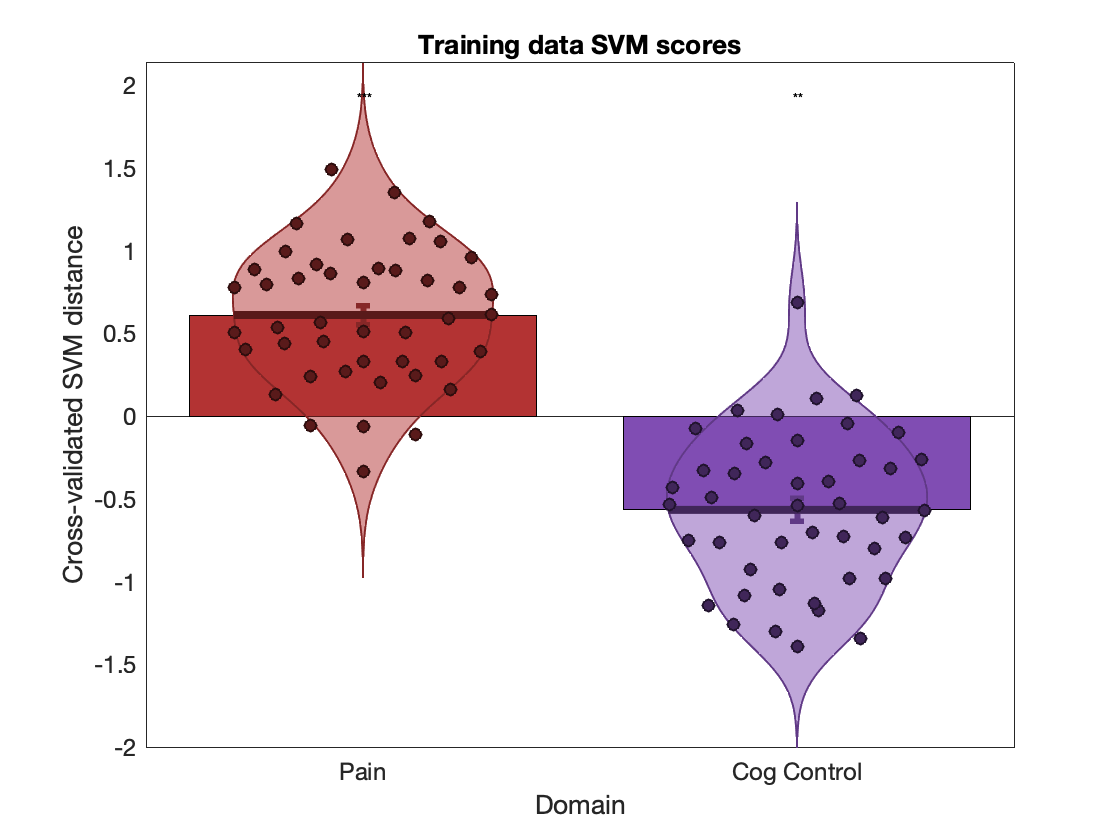

set(gca, 'XTickLabel', {'Pain' 'Cog Control'});
ylabel('Cross-validated SVM distance');
xlabel('Domain')

#### Questions to answer

- How accurate is the model? How sensitive and specific?  Describe in words what these values mean.

- What is the SVM classificaiton boundary here for separating pain from cognitive control? If I have an observation with an SVM distance score of 0.5, for example, what class would the model predict? How about a score of -0.7?

- How many subjects are misclassified here? Do they come more from some subdomains than others? (Note: you will want to create plots to show this that are not in the code example!)

### Display the SVM map and results

Display the unthresholded weight map:

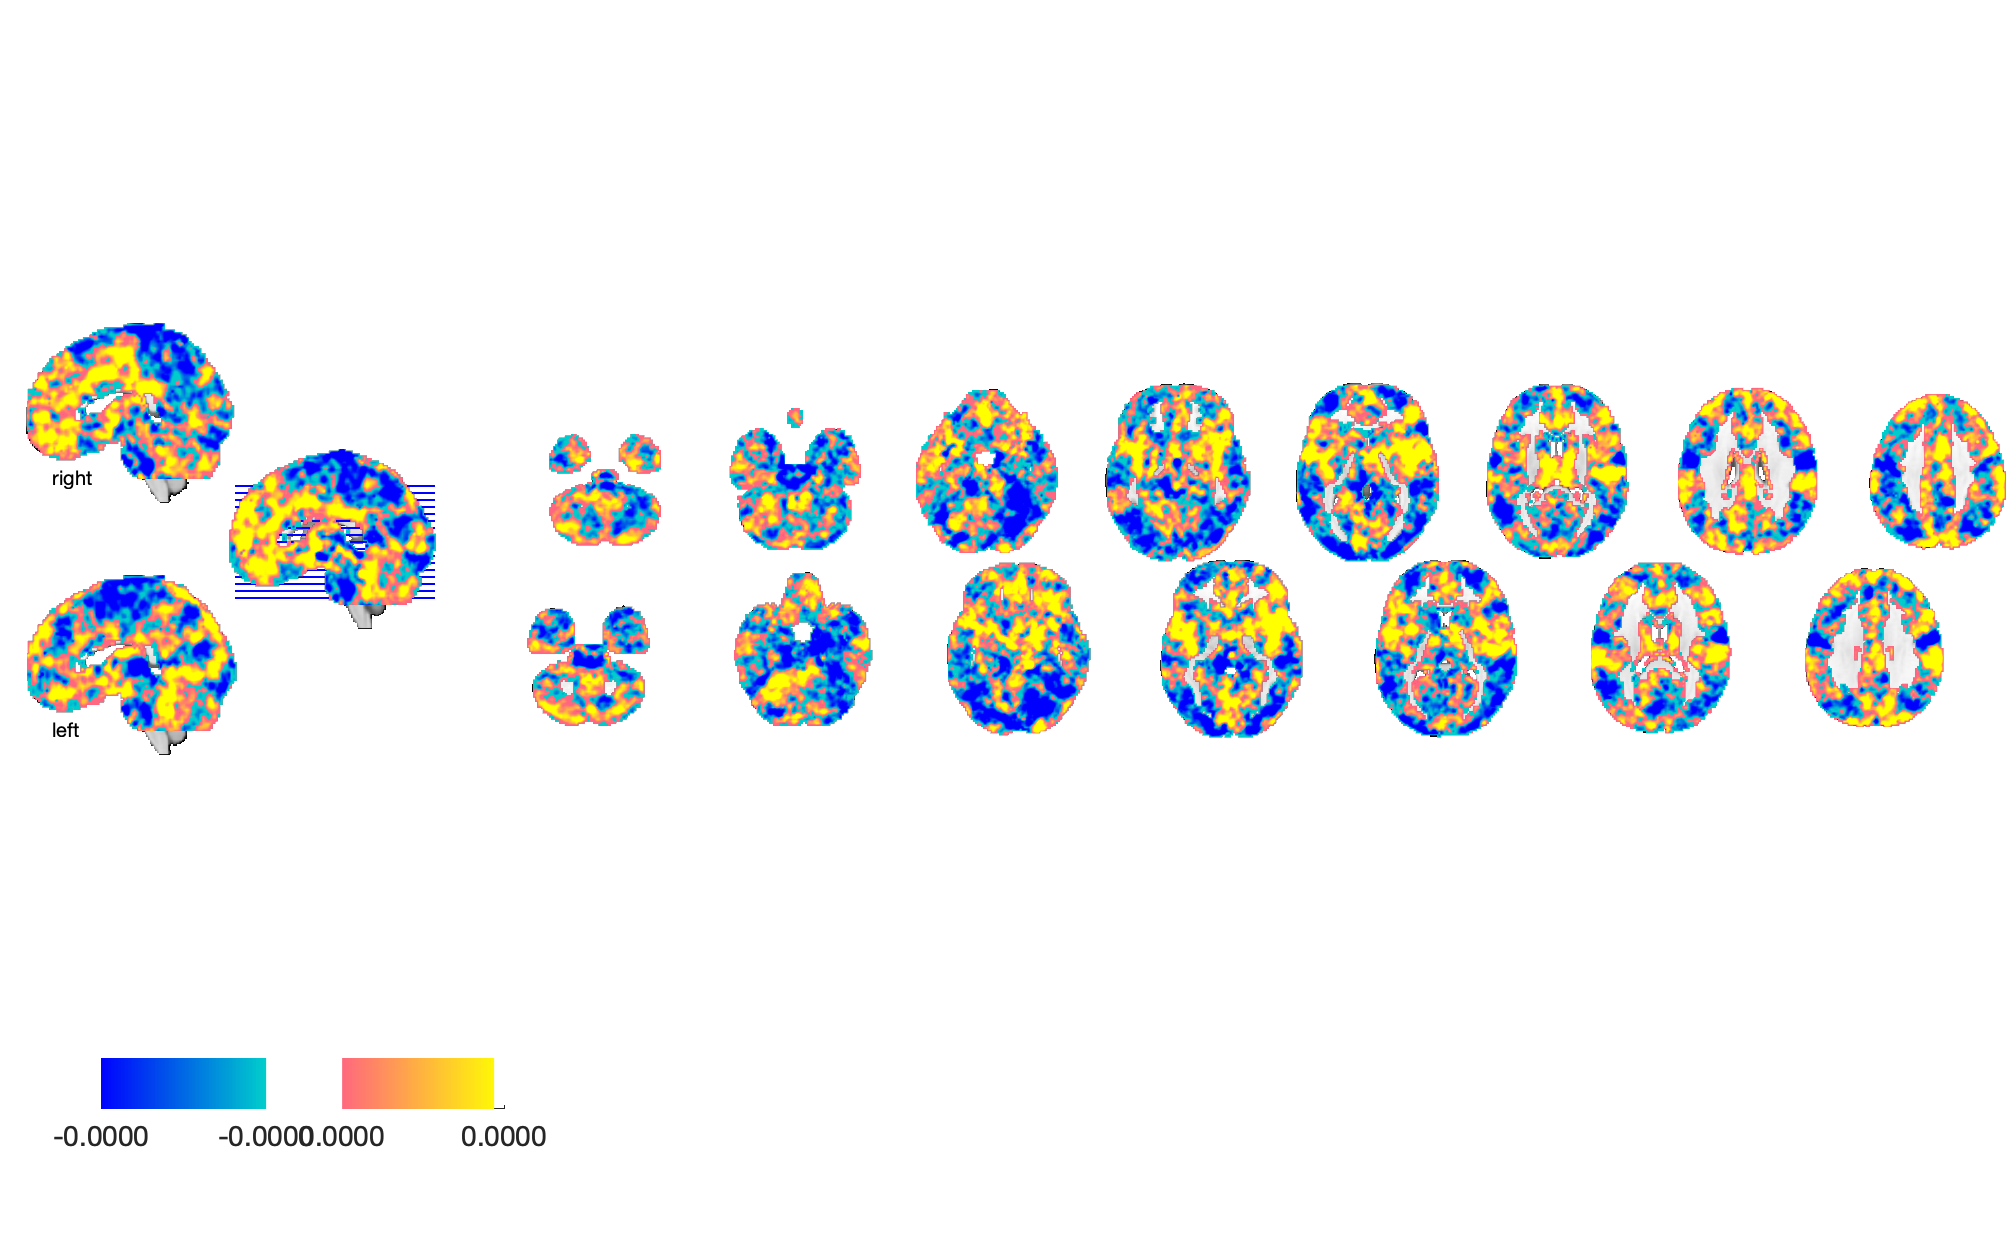

Setting up fmridisplay objects


sagittal montage: 4038 voxels displayed, 197237 not displayed on these slices


sagittal montage: 4000 voxels displayed, 197275 not displayed on these slices


sagittal montage: 3849 voxels displayed, 197426 not displayed on these slices


axial montage: 28960 voxels displayed, 172315 not displayed on these slices


axial montage: 31113 voxels displayed, 170162 not displayed on these slices


create_figure('weight map'); axis off;
montage(stats.weight_obj);

In areas with positive weights, shown in yellow, more activity signals  pain (vs. cognitive control). In areas with negative weights, shown in blue, more activity signals cognitive control (vs. pain). This unthresholded map may be used to make predictions about new test images (e.g., from different participants). 

We'll see how to make inferences about the regions that make significant, stable contributions to prediction in another section below.

#### Questions to answer

- What is the interpretation of positive weights and negative weights? 

- Why are their weights everywhere in the brain? Does this mean that the whole brain is predictive of pain vs. cognitive control?

- If you ran a different classifier, e.g., for pain vs. emotion, would you expect the weights to be very similar or very different? Or a mix of both depending on the region in question? Why?

### Apply the SVM model to an independent test dataset

Now I can apply the model to a new dataset of independent participants. We'll take the dataset from the held-out studies, three pain and three cognitive control. 

We'll calculate the "pattern response" or "pattern expression", which is the dot product of the SVM weight map and each test image. 

We should also add back in the intercept, so that values > 0 are predicted "yesses" and values < 0 are predicted "nos". The intercept (or offset) value is stored in `stats.other_output{3}`. 

% Get the pattern response/expression
test_scores = apply_mask(test_dat, stats.weight_obj, 'pattern_expression');

Number of zero or NaN values within weight mask, by input image:
  0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 



% Add the offset
test_scores = test_scores + stats.other_output{3};   

% Plot the ROC plot
create_figure('ROC')

ans =   Figure (ROC) with properties:

      Number: 1
        Name: 'ROC'
       Color: [1 1 1]
    Position: [561 529 560 420]
       Units: 'pixels'

  Show all properties


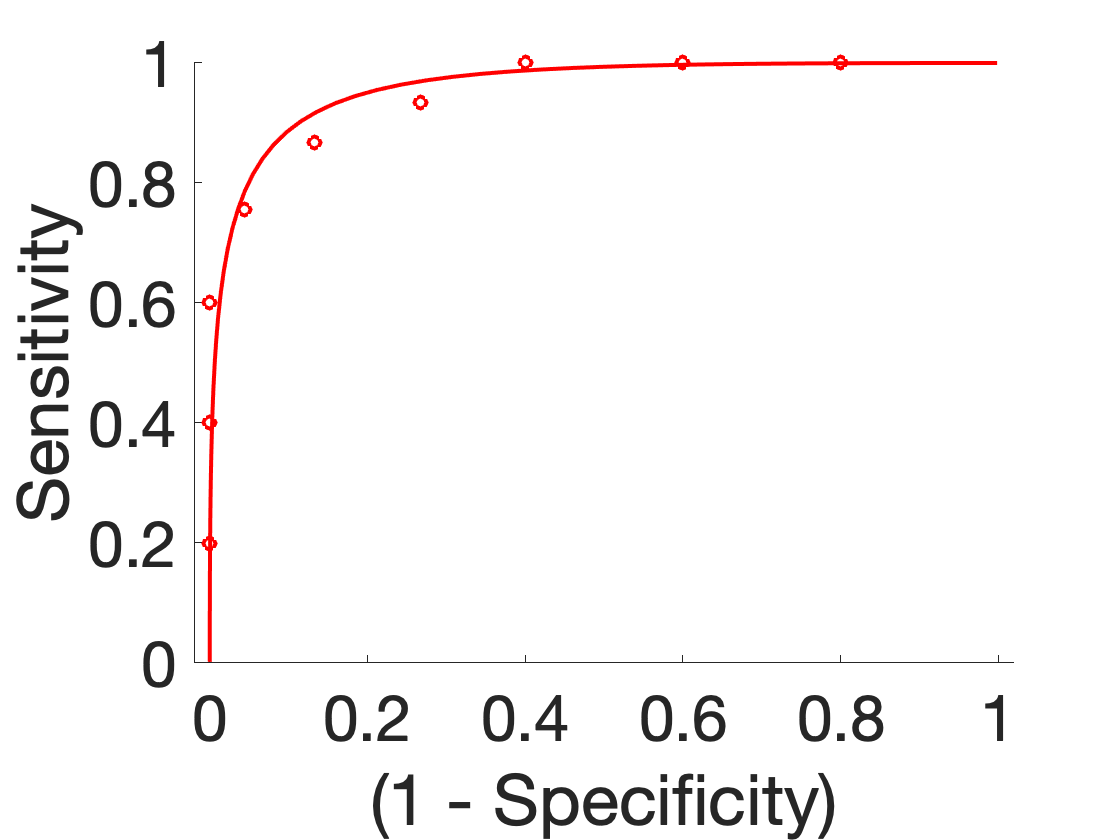


ROC_PLOT Output: Single-interval, A priori threshold
Threshold:	0.00	Sens:	 84% CI(73%-94%)	Spec:	 89% CI(79%-98%)	PPV:	 88% CI(78%-98%)	Nonparametric AUC:	0.96	Parametric d_a:	2.50	  Accuracy:	 87% +- 3.6% (SE), P = 0.000000


ROC = roc_plot(test_scores, logical(test_dat.Y > 0), 'color', 'r', 'threshold', 0);


% Plot the scores
dat_to_plot = {test_scores(test_dat.Y > 0) test_scores(test_dat.Y < 0)};

create_figure('SVM distance scores by class');
barplot_columns(dat_to_plot, 'title', 'Test data SVM scores', 'nofigure', 'colors', {[.7 .2 .2] [.5 .3 .7]})

Column   1:	Column   2:	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error       T           P         Cohens_d
    ___________    __________    _________    _______    __________    ________

    {'Col   1'}      0.64267     0.077502      8.2923    1.5403e-10     1.2361 
    {'Col   2'}     -0.64575     0.076413     -8.4508    9.1708e-11    -1.2598 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {45×2 cell}
        text_han: {45×2 cell}
       point_han: {45×2 cell}
    star_handles: [3.6621e-04 1.0004]


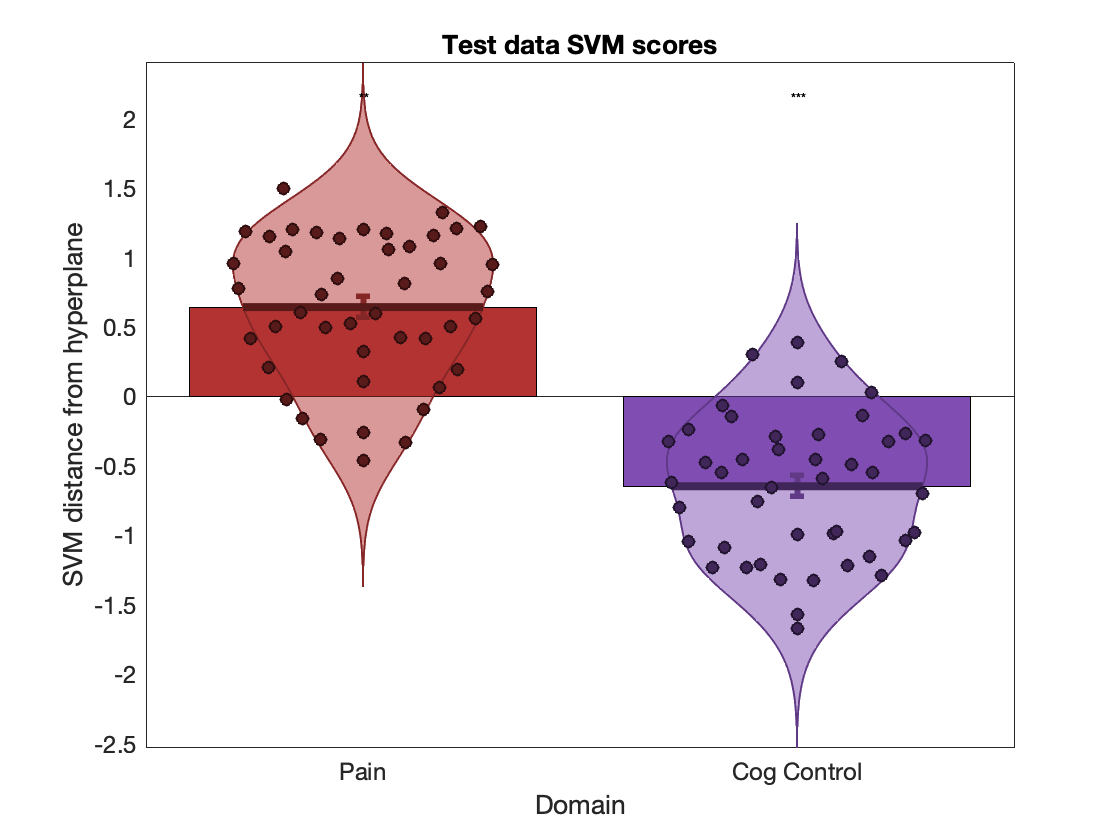

set(gca, 'XTickLabel', {'Pain' 'Cog Control'});
ylabel('SVM distance from hyperplane');
xlabel('Domain')

An accuracy value of 80%, for example, means we can correctly predict whether an image is pain or cognitive control with 80% accuracy on average, across 3 subdomains of each.

#### Questions to answer

- How accurate is the model on the test validation dataset? Is it comparable to the training dataset?

- If it were substantially less accurate, what would you suspect about the cross-validation results? Why?

### Bootstrap the SVM map to get significant regions

Pattern classification is often done on the whole image, but some voxels (those with extreme weights in either positive or negative direction) contribute more than others. Many voxels may not make stable contributions and contribute little. If we're interested in which regions make statistically signfiicant contributions, bootstrapping the weight map is a useful procedure. 

This can take a long time with many, so watch out! We'll use `tic` and `toc` to time it. You might want to try it with a few bootstrap samples first to see if it's working OK. For publication-level precision, at least 10,000 bootstrap samples is preferred, because the  P-values become more precise, and we're often interested in P-values at the tails (e.g., P < 0.001). 

Cross-validated prediction with algorithm cv_svm,   5 folds
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 1.35 sec

Completed fit for all data in:   0 hours   0 min  2 secs 
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.63 sec
Fold 1/5 done in:   0 hours   0 min  1 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.64 sec
Fold 2/5 done in:   0 hours   0 min  1 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.54 sec
Fold 3/5 done in:   0 hours   0 min  1 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.60 sec
Fold 4/5 done in:   0 hours   0 min  1 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 0.55 sec
Fold 5/5 done in:   0 hours   0 min  1 sec

Total Elapsed Time =   0 hours   0 min  6 sec
Number of unique values in dataset: 201275  Bit rate: 17.62 bits
Starting

Bootstrapping weights, 1000 samples...Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 2.24 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 2.59 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 2.77 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 2.29 sec
Testing...
Done in 2.85 sec
Testing...
Done in 2.80 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Training...training svm kernel linear C=1 optimizer=andre.... 
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 2.13 sec
Testing...
Done in 2.17 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done in 2.09 sec
Training...training svm kernel linear C=1 optimizer=andre.... 
Testing...
Done i

tic

[cverr, stats, optout] = predict(training_dat, 'cv_svm', 'bootweights', 'bootsamples', 1000);


toc

Elapsed time is 806.717441 seconds.


 Now, the stats.weight_obj is a `statistic_image` object that includes P-values. I can threshold the weight image and display it:

w = stats.weight_obj;

w = threshold(w, 0.05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.004077

Image   1
444 contig. clusters, sizes   1 to 3028
Positive effect: 7522 voxels, min p-value: 0.00000000
Negative effect: 8891 voxels, min p-value: 0.00000000


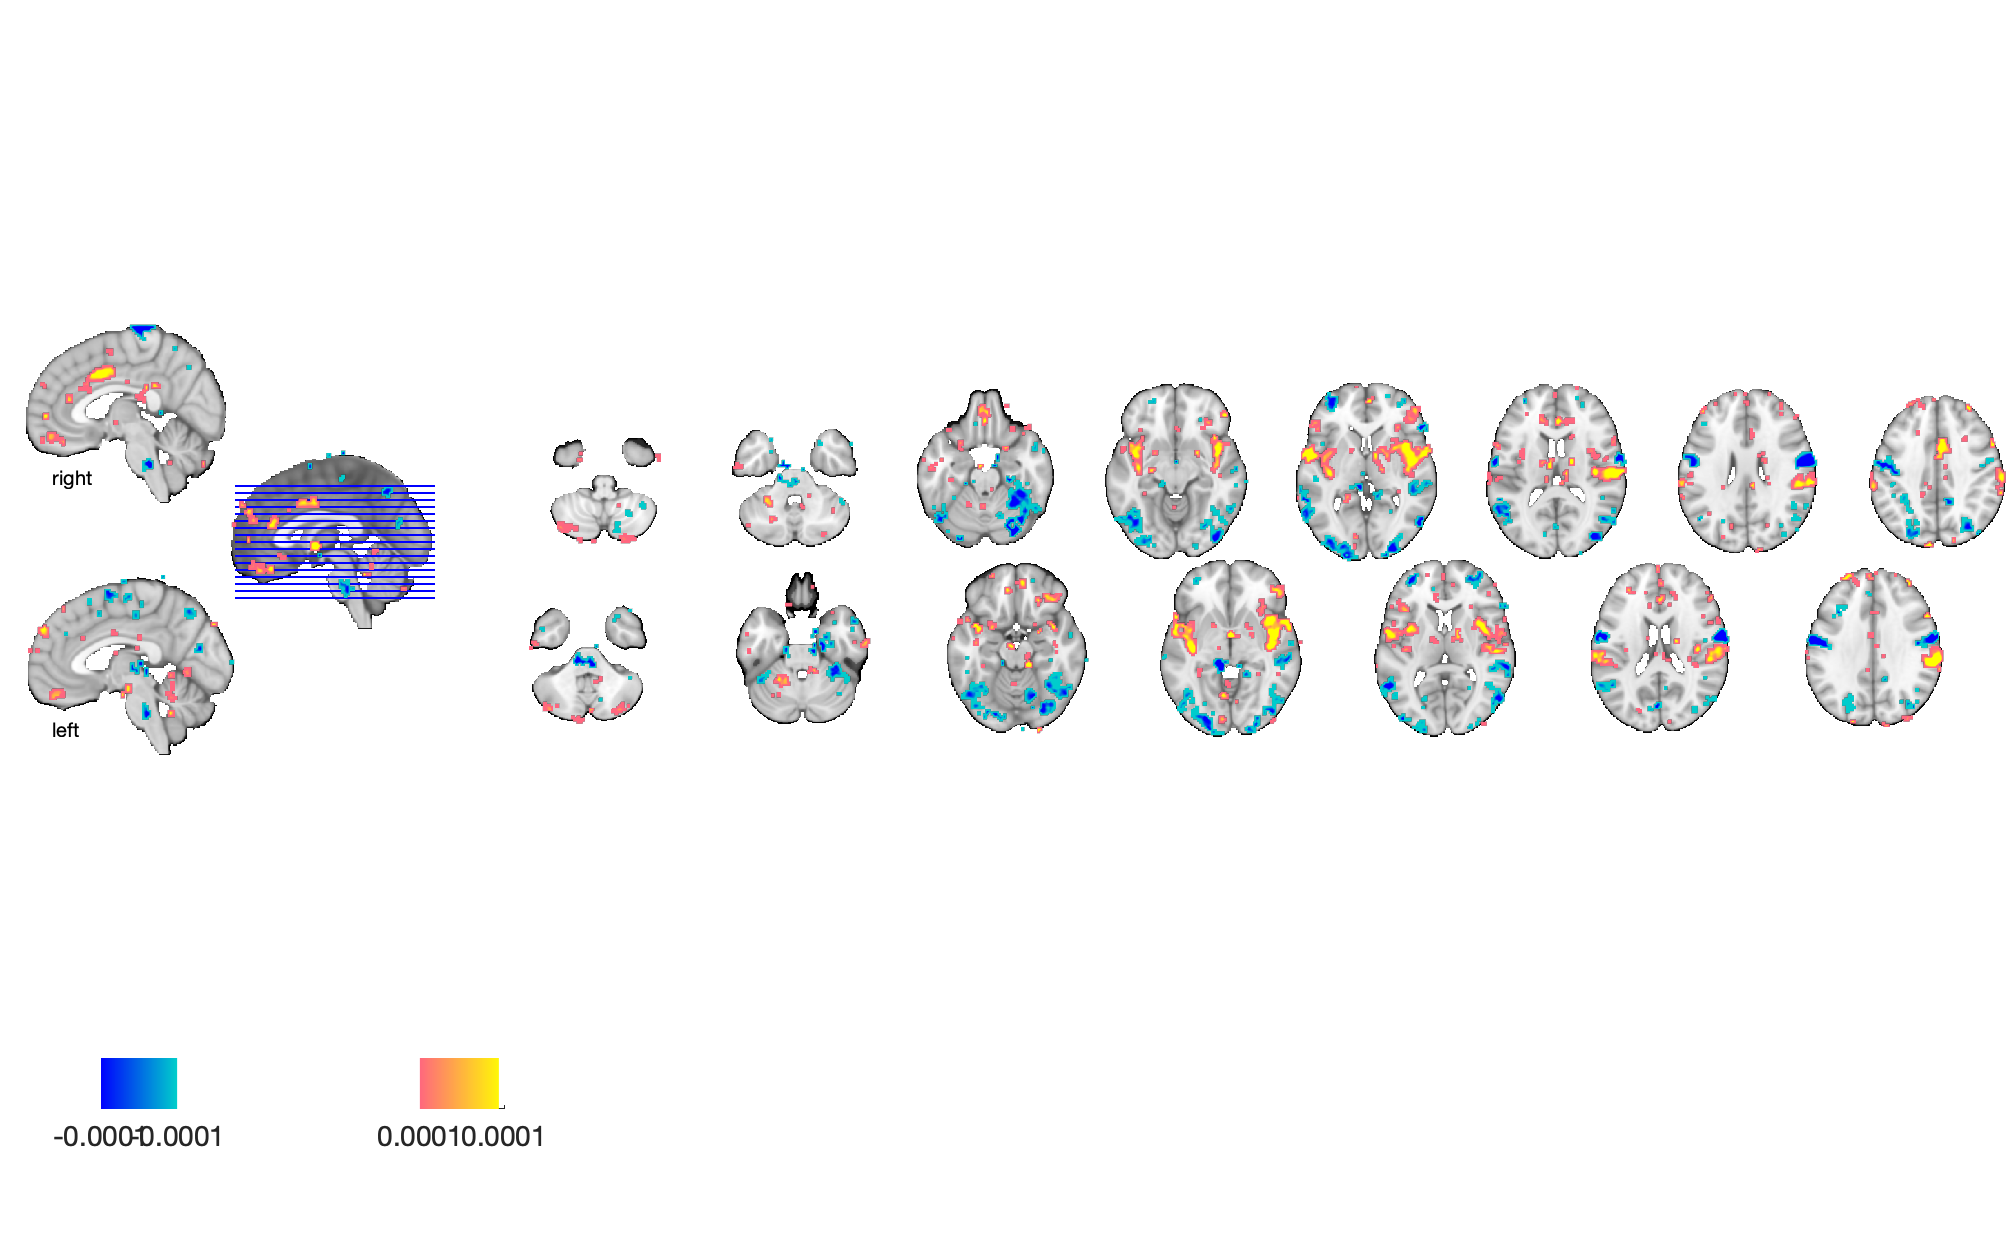

Setting up fmridisplay objects


sagittal montage: 163 voxels displayed, 16250 not displayed on these slices


sagittal montage: 146 voxels displayed, 16267 not displayed on these slices


sagittal montage: 143 voxels displayed, 16270 not displayed on these slices


axial montage: 2418 voxels displayed, 13995 not displayed on these slices


axial montage: 2586 voxels displayed, 13827 not displayed on these slices



create_figure('weight map'); axis off;
montage(w);

#### Recursive Feature Elimination (RFE)

Another way to get a reduced model with significant features is Recursive Feature Elimination (RFE).  For example:

#### Questions to answer

- What threshold did we use above, and what is the interpretation of this threshold in words?

- How many voxels are significant in the thresholded map?

- Which regions show significant positive and negative weights? Use an atlas object to help label them, and make a table. Which large-scale networks are the positive regions associated with? Which networks for negative regions?

### Apply the bootstrap-thresholded SVM model to an independent test dataset

Bootstrapping and RFE are forms of feature selection -- ways of identifying features that are particularly important.  Features selection can improve model performance (e.g., accuracy, etc.) in many cases. It can also result in a simpler and more easily interpretable model.

However, it's not appropriate to perform feature selection and test model performance on the same dataset, as this is a circular process that can bias accuracy in an over-optimistic direction. If feature selection on the training dataset is desired, it can be done within a nested cross-validation loop. This is beyond the scope of this lab. However, it is also possible, and much simpler, to select features on an initial training dataset and apply it to an independent test dataset  to validate and assess performance. This is precisely the situation we have here. 

Let's apply the thresholded model to our test dataset. This is only the second model we're testing on the test dataset, so there is little risk of overfitting -- we're comparing only two models (the unthresholded and thresholded ones).

As before, we'll calculate the "pattern response" or "pattern expression", which is the dot product of the SVM weight map and each test image. We'll also add back in the intercept, so that values > 0 are predicted "yesses" and values < 0 are predicted "nos". The intercept (or offset) value is stored in `stats.other_output{3}`. 

***w*** must be a *statistic_image* object for this to work. This type of object is returned when you apply bootstrapping in *predict()*. 

% Get the pattern response/expression
% w was thresholded above, so this is a reduced model including selected
% voxels only
test_scores = apply_mask(test_dat, w, 'pattern_expression');

% Add the offset
test_scores = test_scores + stats.other_output{3};   

% Plot the ROC plot
create_figure('ROC')

ans =   Figure (ROC) with properties:

      Number: 1
        Name: 'ROC'
       Color: [1 1 1]
    Position: [561 529 560 420]
       Units: 'pixels'

  Show all properties


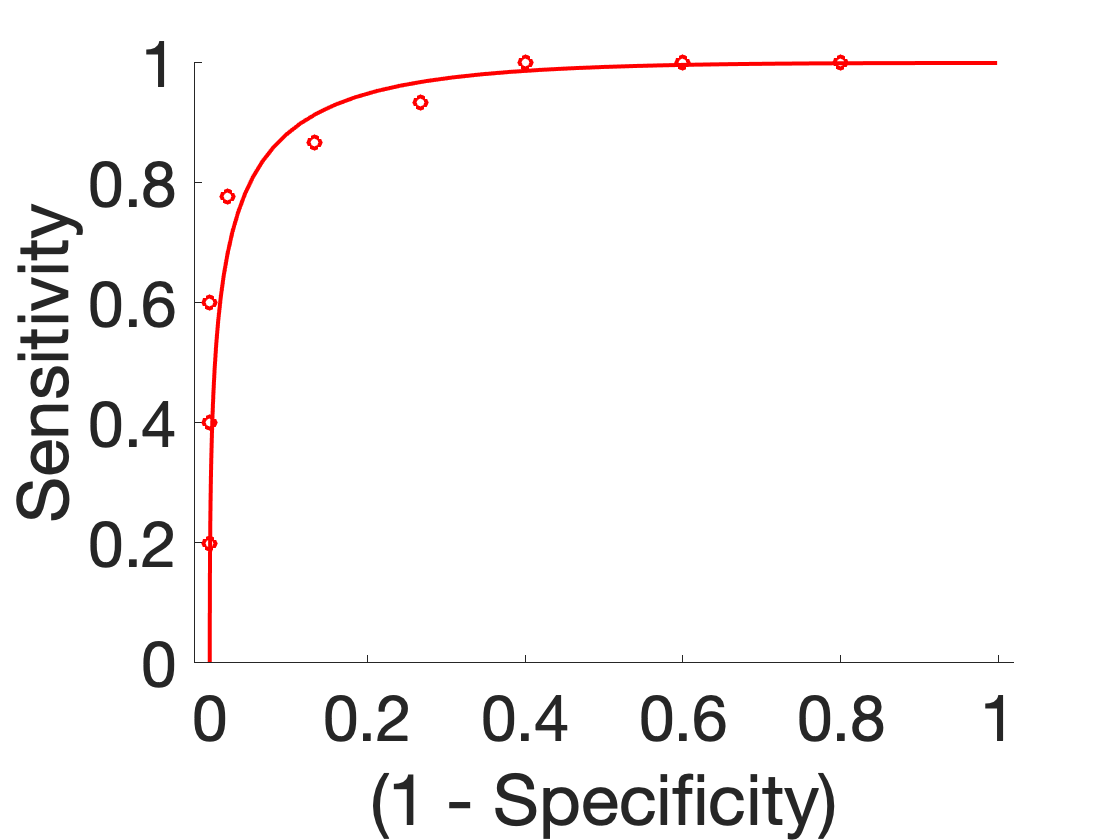


ROC_PLOT Output: Single-interval, A priori threshold
Threshold:	0.00	Sens:	 80% CI(67%-91%)	Spec:	 93% CI(85%-100%)	PPV:	 92% CI(83%-100%)	Nonparametric AUC:	0.96	Parametric d_a:	2.48	  Accuracy:	 87% +- 3.6% (SE), P = 0.000000


ROC = roc_plot(test_scores, logical(test_dat.Y > 0), 'color', 'r', 'threshold', 0);


% Plot the scores
dat_to_plot = {test_scores(test_dat.Y > 0) test_scores(test_dat.Y < 0)};

create_figure('SVM distance scores by class');
barplot_columns(dat_to_plot, 'title', 'Test data SVM scores', 'nofigure', 'colors', {[.7 .2 .2] [.5 .3 .7]})

Column   1:	Column   2:	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error       T           P         Cohens_d
    ___________    __________    _________    _______    __________    ________

    {'Col   1'}      0.23816     0.040012      5.9523    3.9662e-07    0.88731 
    {'Col   2'}     -0.41533     0.038601     -10.759    6.6595e-14    -1.6039 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {45×2 cell}
        text_han: {45×2 cell}
       point_han: {45×2 cell}
    star_handles: [4.8828e-04 1.0005]


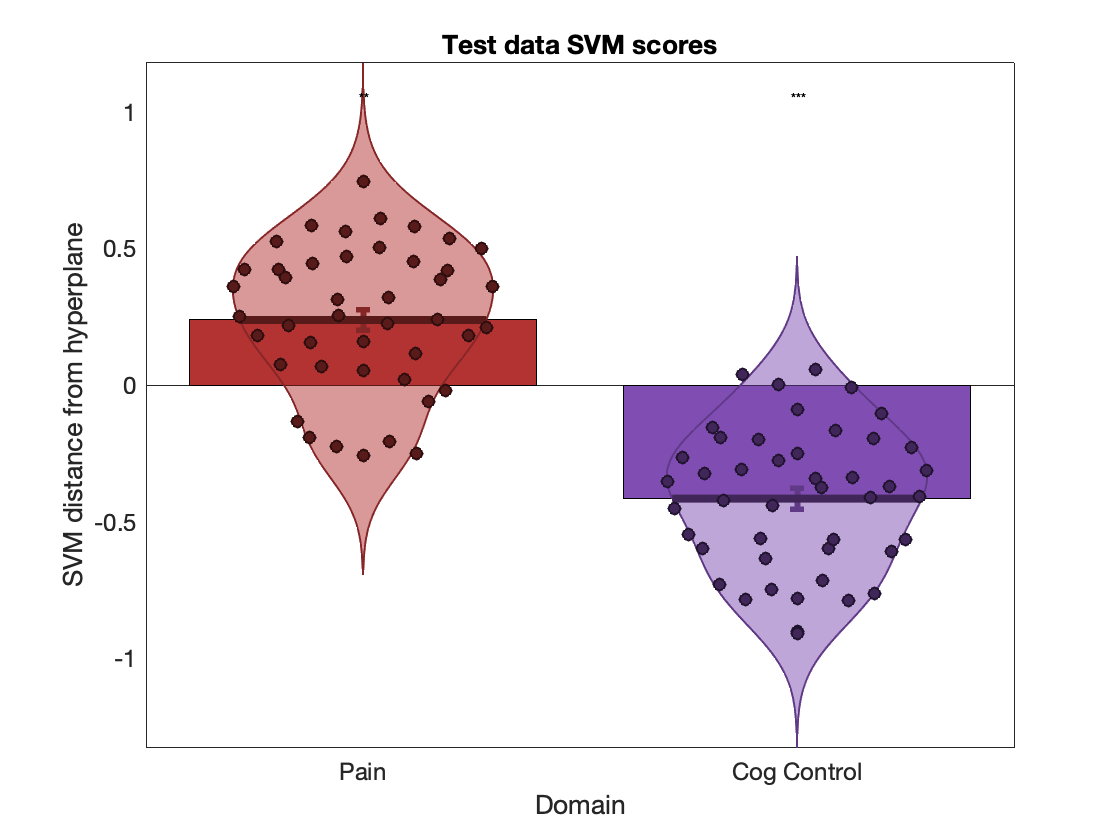

set(gca, 'XTickLabel', {'Pain' 'Cog Control'});
ylabel('SVM distance from hyperplane');
xlabel('Domain')


% Confusion matrix
yfit = double(test_scores > 0) - 0.5;     % Predicted "yes" or "no" using original SVM boundary of 0 for class membership
true_y = double(test_dat.Y > 0) - 0.5;    % Cast as double and use non-zero values to indicate classes for confusion_matrix

[m,aprime,corr,far,missclass, mprop, statstable] = confusion_matrix(true_y, yfit);

mytable = array2table(mprop, 'VariableNames', {'Pred Cog' 'Pred Pain'}, 'RowNames', {'Actual Cog' 'Actual Pain'});
disp(mytable)

                   Pred Cog    Pred Pain
                   ________    _________

    Actual Cog     0.93333     0.066667 
    Actual Pain        0.2          0.8 




disp(statstable)

    Freq    Perc_cases     Sens       Spec        PPV      Aprime
    ____    __________    _______    _______    _______    ______

     45        0.5        0.93333        0.8    0.82353    2.3427
     45        0.5            0.8    0.93333    0.92308    2.3427



#### Questions to answer

- How correlated are the test_scores from the reduced (bootstrapped) model with the full (unthresholded) model? (Note: you will have to go back and re-estimate them, save them as a different variable, and plot/test their correlaiton).

- How accurate is the reduced model in terms of sensitivity and specificity? What is the effect size, and is it large? Is the reduced model an acceptable alternative to the full model?

- How well does the model generalize across subdomains of pain and cognitive control? Are some types of pain or cognitive control misclassified at higher rates than others?